# Steel ordering and shipping_11.22

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

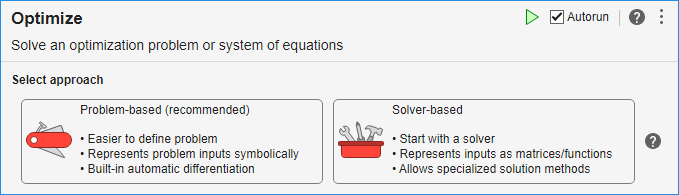

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% 创建优化变量
flagi2 = optimvar("flagi",1,7,"Type","integer","LowerBound",0,"UpperBound",...
    1);
Xij2 = optimvar("Xij",7,15,"Type","integer","LowerBound",0,"UpperBound",...
    2000);
Rj2 = optimvar("Rj",1,15,"Type","integer","LowerBound",0,"UpperBound",1000);
Lj2 = optimvar("Lj",1,15,"Type","integer","LowerBound",0,"UpperBound",1000);

% 设置求解器的初始起点
initialPoint.flagi = zeros(size(flagi2));
initialPoint.Xij = zeros(size(Xij2));
initialPoint.Rj = zeros(size(Rj2));
initialPoint.Lj = zeros(size(Lj2));

% 创建问题
problem = optimproblem;

% 定义问题目标
problem.Objective = fcn2optimexpr(@objectiveFcn,Xij2,Rj2,Lj2);

% 定义问题约束
problem.Constraints.constraint1 = constraintFcn3(Xij2,Rj2,Lj2);
problem.Constraints.constraint2 = constraintFcn2(flagi2,Xij2);
problem.Constraints.constraint3 = constraintFcn(flagi2,Xij2);

% 设置非默认求解器选项
options = optimoptions("ga","MutationFcn","mutationpower","UseParallel",true,...
    "PlotFcn",["gaplotselection","gaplotbestf","gaplotbestindiv",...
    "gaplotexpectation"]);

% 求解问题
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","ga","Options",options);

将使用 ga 求解问题。


错误使用 matlab.ui.Figure/get
对象无效或已删除。

出错 gadsplot (第 202 行)
    plotState.(solver).position = get(fig,'Position');

出错 galincon (第 107 行)
    state = gadsplot(options,state,currentState,gaPlotTitle);

出错 gapenalty

出错 


% 显示结果
solution
reasonSolverStopped
objectiveValue

% 清除变量
clearvars flagi2 Xij2 Rj2 Lj2 initialPoint options reasonSolverStopped...
    objectiveValue

## 目标函数

function objective = objectiveFcn(Xij,Rj,Lj)
% 此函数应返回一个表示优化目标的标量。
% 编辑以下行以添加您的计算方法。
data = load("E:\数模\训练题\钢材产出及运输\data.txt");
c = data(1:7, 1:15);
Price_i = data(1:7, 16);
Xi = sum(Xij, 2);

C_order = sum(Xi.*Price_i);
C_freight = sum(sum(c.*Xij));
C_paving = (sum(Rj.*Rj) + sum(Lj.*Lj)) * 0.05;

objective = C_freight + C_order + C_paving;
end

%1
function constraints = constraintFcn3(Xij,Rj,Lj)
% 约束是由一个比较运算符(==)分隔的两个表达式。
len = [104, 301, 750, 606, 194, 205, 201, 680, 480, 300, 220, 210, 420, 500];
con5 = [];
for i = 1:14
    con5 = [con5, Rj(i) + Lj(i+1)];
end

for j = 1:15
    constraints(j) = sum(Xij(:, j)) == Rj(j) + Lj(j);
end
constraints(16) = Rj(1) == 0;
constraints(17) = Lj(15) == 0;
for k = 1:14
    constraints(k + 17) = con5(k) == len(k);
end

    constraints(32) = sum(Xij(7, 1:15)) == 0;
end

%2
function constraints = constraintFcn2(flagi,Xij)
% 约束是由一个比较运算符(<=)分隔的两个表达式。
data = load("E:\数模\训练题\钢材产出及运输\data.txt");
si = data(1:7, 17);

for i = 1:7
    constraints(i) = sum(Xij(i, :)) <= flagi(i) * si(i);
end

end

%3
function constraints = constraintFcn(flagi,Xij)
for i = 1:7
    constraints(i) = sum(Xij(i, :)) >= flagi(i) * 500;
end

end
